# **assess the agreement between raters on coughvid dataset**

% remove previous data
close all; clc; clear;

% load metadata
load ../../ds/ds_load_coughvid

% see all possible options for each category
opt_status = unique(md.status); % covid status
opt_quality = unique(md.quality_1); % cough quality
opt_diagnosis = unique(md.diagnosis_1); % covid diagnosis

% find subjects with raters' diagnosis

diagnosis = string(table2cell(md(:, [7 9 11 13])));
diagnosis_table = md(:, [7 9 11 13]);

status_logic = md.status ~= "";
num_raters_logic = sum(diagnosis ~= "", 2) == 4;

logic = status_logic & num_raters_logic;
diagnosis_table = diagnosis_table(logic, :);
diagnosis = diagnosis(logic, :);
status = string(md.status(logic, :));
status_table = array2table(status, "VariableNames", "subj_status");

#### ratets' diagnoses

num_rows =15;
disp([status_table(1 : num_rows, :), diagnosis_table(1 : num_rows, :)]);

     subj_status         diagnosis_1              diagnosis_2                diagnosis_3              diagnosis_4    
    _____________    ___________________    _______________________    _______________________    ___________________

    "symptomatic"    {'healthy_cough'  }    {'COVID-19'           }    {'upper_infection'    }    {'lower_infection'}
    "COVID-19"       {'lower_infection'}    {'lower_infection'    }    {'lower_infection'    }    {'lower_infection'}
    "healthy"        {'lower_infection'}    {'COVID-19'           }    {'healthy_cough'      }    {'healthy_cough'  }
    "COVID-19"       {'COVID-19'       }    {'obstructive_disease'}    {'obstructive_disease'}    {'upper_infection'}
    "healthy"        {'COVID-19'       }    {'upper_infection'    }    {'obstructive_disease'}    {'upper_infection'}
   

% measure amount of agreement

agreement_mat = [ ...
    sum(diagnosis == 'COVID-19', 2), ...
    sum(diagnosis == 'healthy_cough', 2), ...
    sum(diagnosis == 'lower_infection', 2), ...
    sum(diagnosis == 'obstructive_disease', 2), ...
    sum(diagnosis == 'upper_infection', 2) ...
    ];

agreement_table = table( ...
    'Size', [length(diagnosis), length(opt_diagnosis)], ...
    'VariableTypes', {'string', 'double', 'double', 'double', 'double', 'double'}, ...
    'VariableNames',{ ...
        'status' ...
        'COVID-19' ...
        'healthy_cough' ...
        'lower_infection' ...
        'obstructive_disease' ...
        'upper_infection'} ...
    );

agreement_table{:, 1} = status;
agreement_table{:, 2:end} = agreement_mat;

#### agreement matrix

No. votes (1 per rater) for each category.

num_rows =10;
disp(agreement_table(1 : num_rows, :));

       status        COVID-19    healthy_cough    lower_infection    obstructive_disease    upper_infection
    _____________    ________    _____________    _______________    ___________________    _______________

    "symptomatic"       1              1                 1                    0                    1       
    "COVID-19"          0              0                 4                    0                    0       
    "healthy"           1              2                 1                    0                    0       
    "COVID-19"          1              0                 0                    2                    1       
    "healthy"           1              0                 0                    1                    2       
    "symptomatic"       2              

## fleiss'es kappa

**Fleiss' kappa** is a [statistical measure](https://en.wikipedia.org/wiki/Statistical_measure) for assessing the [reliability of agreement](https://en.wikipedia.org/wiki/Inter-rater_reliability) between a fixed number of raters when assigning [categorical ratings](https://en.wikipedia.org/wiki/Categorical_rating) to a number of items or classifying items. This contrasts with other kappas such as [Cohen's kappa](https://en.wikipedia.org/wiki/Cohen%27s_kappa), which only work when assessing the agreement between not more than two raters or the intra-rater reliability (for one appraiser versus themself). The measure calculates the degree of agreement in classification over that which would be expected by chance.

The kappa K can be defined as:

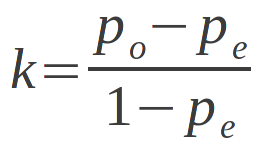

The factor $1-P_e$ gives the degree of agreement that is attainable above chance, and $P_0 -P_e$ gives the degree of agreement actually achieved above chance. If the raters are in complete agreement then $k=1$. If there is no agreement among the raters (other than what would be expected by chance) then $k\le 0$.

table for interpreting k values:

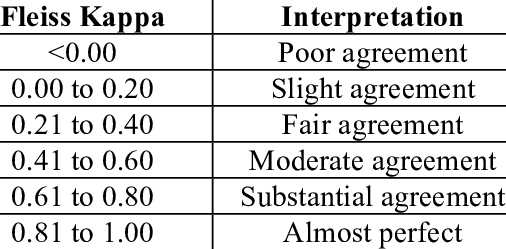

#### fleiss'es kappa results:

fleiss_kappa(agreement_mat);

               COVID-19     healthy_cough    lower_infection    obstructive_disease    upper_infection
               _________    _____________    _______________    ___________________    _______________

    kappa      -0.047926        0.17869           0.18459              0.13909           -0.0042288   
    se          0.039653       0.039653          0.039653             0.039653             0.039653   
    Z            -1.2086         4.5065            4.6552               3.5076             -0.10665   
    p-value       0.2268      6.592e-06        3.2371e-06           0.00045213              0.91507   

    Fleiss_k     error     Confidence_Interval     Agreement       